# Lab 6

Kuan-Wei Lee

Student#: 1663855

Lab partner: Megan Miyasaki

## Problem 1

For problem 1 , I am going to make a Poisson distribution with mean = 100 and treat it as a background distribution.

clear all 
close all
clc

mean = 100;
N = 10000;
background = random('Poisson',mean,[1, N]);

The code above generated 10000 Poisson distributed random numbers.

To locate the 5 sigma thrshold, we are basically asking a statistical question: What is the strength of the signal X such that the probability of getting a signal that is equal to or greater than X from the background is 5 sigma (1/3.5*10^6)?

To answer this question, we then have to solve for X by evaluating the following integral:


$$\int_X^{\infty } \mathrm{pdf}\left(x\right)\mathrm{dx}=\frac{1}{3\ldotp 5*{10}^6 }$$


The matlab code below will solve the equation listed above.

I first fit the backgroud distribution with a Poisson distribution and then integrate the pdf that fits the background signals.

P = 1/3.5e6;
pd = fitdist(background','Poisson');
X = icdf(pd,1-P);

 It turnd out the the 5 sigma threshold "X" is at 154.

## **Problem 2**

In this section, I am going to inject some signals to the background. I am going to generate 1000 strong signals that is correspond to 8 sigma. To achieve that, I am going to find the signal strngths that correspond to 8 sigma. After finding the values that correspond to 8 sigma (X_8), I will make a vector that has 1000 X_8 values.

To locate the value of X_8, I will first determine the 8 sigma probability with the Gaussian distribution. After the probability is determined, I will evaluate the equation listed in the section 1 to solve for the values of X_8.

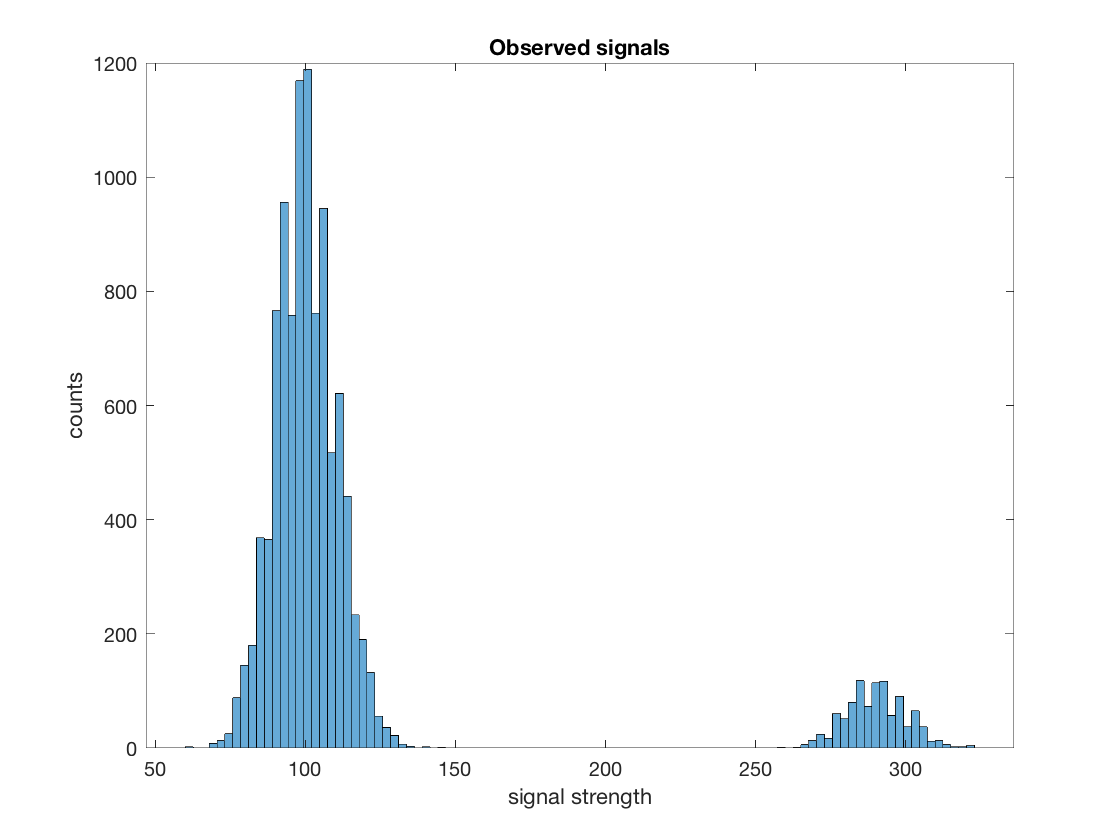

P_8sigma = 1-cdf('Normal',8,0,1);

X_8 = icdf(pd,1-P_8sigma);
index =randi([1 N],1,1000);
noise = background(index);
signal_inj = 190.*ones(1,1000)+noise;
observ_signal = [background signal_inj] ;
histogram(observ_signal,100)
title('Observed signals')
xlabel('signal strength')
ylabel('counts')

The value of X_8 was found to be 190. To inject the signal of 190 into the background signals 1000 times, I pick 1000 random numbers from the background distribution and add 190 to each of the 1000 random numbers. The reason for doing that is to simulate the measurements. In the real world observations, the signal we measure on our devices will be the true signal we are observing plus the random noise from the background.

The histogram is showing that the majority of the signals are around 100 because most of the signals are background. However, there are some signals situate around 290. 190 is actually the true signal that we are observing, the signals around 290 are the uncertianty of the observed signal. The reason why there are uncertianties is because of the background signal. When the detector observes a signal source for multiple times, alothough the signal source does not change in strength, the signals observed by the detector may fluctuate by some small amount. 

From the distribution of the signal strength around 290, we can see that it leans toward the right side and looks like a Poisson distribution. This suggests that the probability of observing a signal that is stronger than 290 is lower than the probability of observing a signal that is weakwe than 290. When integrating the Poisson distribution pdf from 0 to the mean, the probability is about 52. In our case the mean of the Poisson distribution around the observed signal has a mean of 290. Therefore, the probability of observing a signal that is lower than 290 is higher. 

One thing to notice is that the distribution of observed signal is biased. Since our true signal is 190, we would expect the distribution of the observed signal is around 190. The reason why our distribution is biased is because the background is very strong. 

## **Problem 3 **

In this problem, I am going to inject signals in the range of 0 - 300 (a signal strength that is far away from the mean). I chose 1000 signals range from 0 - 300 and inject each signals 1000 times into the background data. The way I inject each signal is making a vector that contains 1000 signal values that will be injected. Pick 1000 random values from the background data, throws them in a vector and make it a "noise" vector. Then the observed signal will be the sum of the noise vector and the injected signal vector. By doing this, we are basically simulating the data. When we make measurement in the real world, the signal readings on the detector will be the true signal that we are observing plus the random noise. By picking 1000 random values from the background and add it to the injected signal, we are basically saying that the injected signal is the true signal we are observing and the random value chosen from the background is the noise of a given measurement.

The code below inject signals that range from 0 to 300 1000 for each signal. 

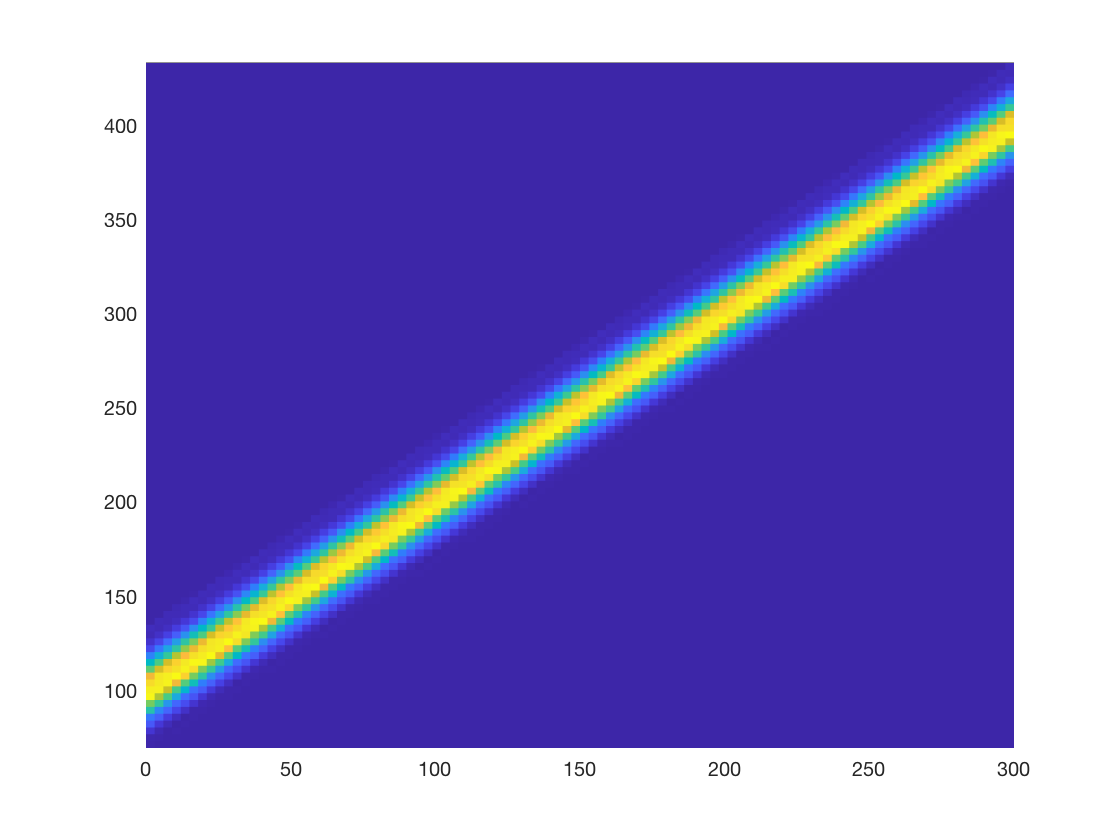

size = 1000;
signalstrength = linspace(0,300,1000);
[scratch signal] = meshgrid(signalstrength);

noise = repmat(background(index),1000,1);
obssignal = noise + signal;

histogram2(signal,obssignal,100,'DisplayStyle','tile','ShowEmptyBins','on')

The yellow band is the uncertainty of the measurement. There are two ways we can look at it. The width of the band can tell us : 1. If we know the value of the true signal that we are observing, what is the range of the signal we can measure on our detector? 2. If we observed a signal on our detector, what is the range of the true signal?

If we pick the injected signal value that is the same as the value we chose in problem 2, the distribution of the observed signal should be the same because we simulate the observed signal in a exact same way.

The code below will plot the distribution of the observed signal if the injected signal is 190.

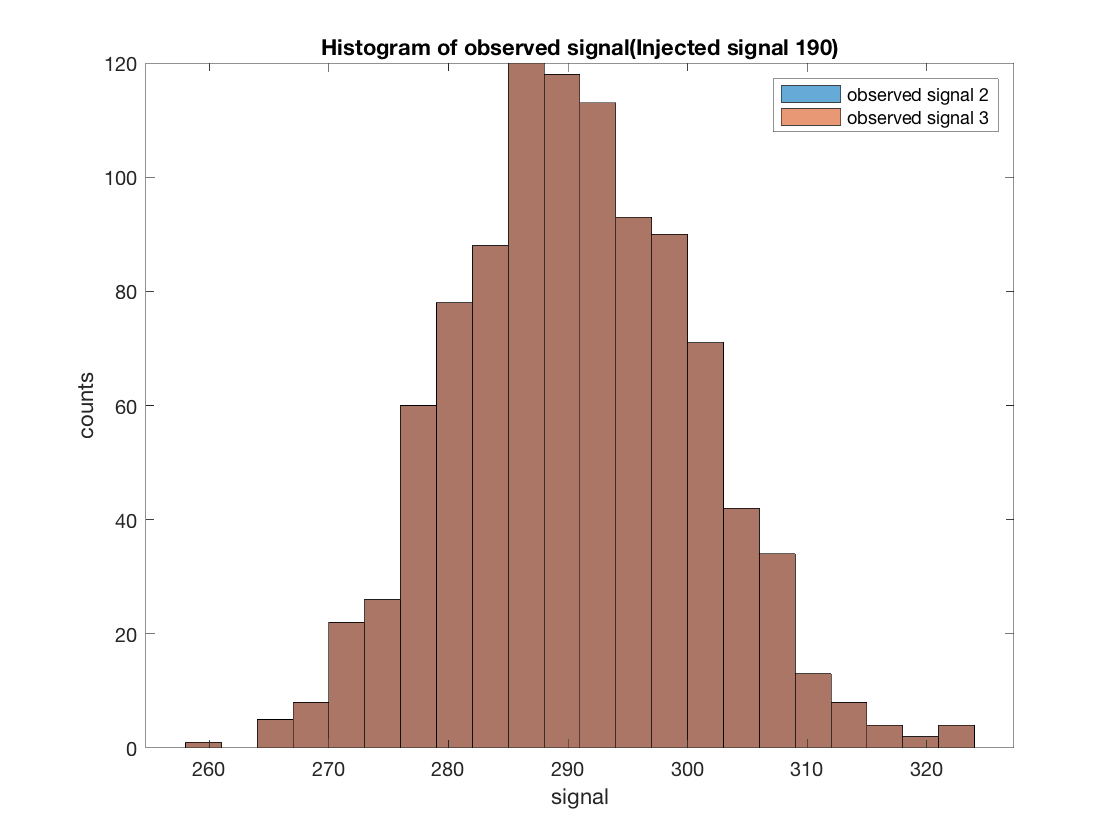

histogram(obssignal(634,:));
hold on
histogram(signal_inj);
hold off
title('Histogram of observed signal(Injected signal 190)')
xlabel('signal')
ylabel('counts')
legend('observed signal 2','observed signal 3')

As the histogram shows, when the injected signal is 190, the distribution of observed signal we got from problem 2 and 3 overlaps.

Now we see the distribution of the observed signal for a given true signal. It will be interesting to see the reverse case where we pick a observed signal and plot the distribution of the true signal. The observed signal is chosen to be 300.

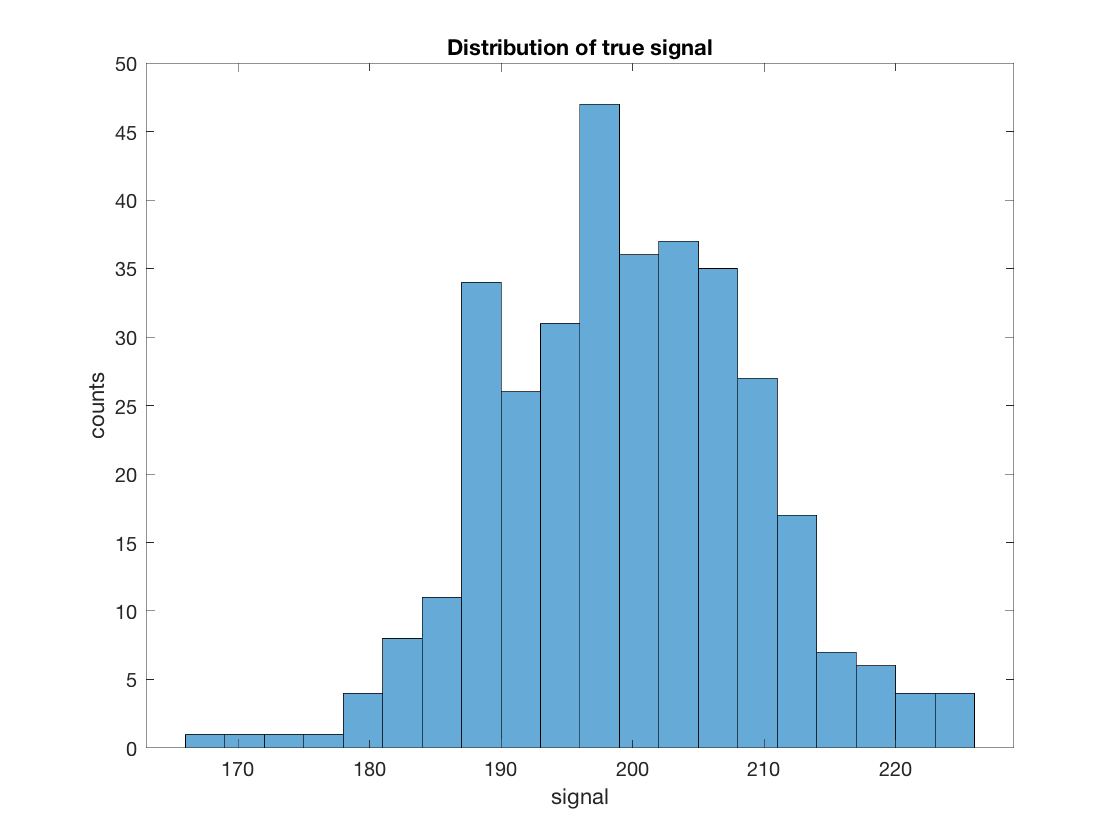


observation = 300;
injected = signal(abs(obssignal-observation)<0.05);
histogram(injected,20)
title('Distribution of true signal')
xlabel('signal')
ylabel('counts')

This histogram shows what is the range of values that the true signal can be and the probability of the true signal being those values if we observe a signal of 300. 

Since we have found the distribution of the true signal, we can try to find the 1 sigma uncertainty on the true signal strength. First, I am going to fit the distribution of the true signal with a Poisson distribution (the shape of the distribution looks like a Poisson) to find the probability distribution function (pdf) of the true signal distribution. After we find the 1 sigma uncertainty range by evaluating the follwing mathmatic equation:

$0\ldotp 33=\int_{\mathrm{X1}}^{\mu } \mathrm{pdf}\left(x\right)\mathrm{dx}$ (The probability of getting a value between X1 and the mean is 0.33 (1 sigma probability))

$0\ldotp 33=\int_{\mu }^{\mathrm{X2}} \mathrm{pdf}\left(x\right)\mathrm{dx}$ The probability of getting a value between mean and X2 is 0.33(1 sigma probability).

We are basically finding the boundary X1 and X2 where the probability of the true signal has a value between X1 and X2 is 66%.

The code below will find the boundary X1 and X2.

pd = fitdist(injected,'Poisson');
lambda = 200.137;
%The mean of the true signal distribution is 200.137
P_mean = cdf(pd,lambda);
X1 = icdf(pd,P_mean-0.33);
X2 = icdf(pd,P_mean+0.33);

In the end, X1 = 154 and X2 = 187. It means that the 1 sigma uncertainty range of the true signal is [154,187].

It seems that the 1 sigma uncertainty range of the true signal is not symmetrical. The left boundary (154) is farther away from the mean (200) than the right boundary (187). This makes sense because our background distribution is not symmetrical. The probability of getting a noise that is weaker than 100 is higher than getting a noise that is stronger than 100. We know that the observed signal is 300 and it is (noise + true signal). Since the noise is more likely to be lower than 100, the probability of the signal being stronger than 200 is higher. The distrubution of the true signal range is leaning toward the righer and the right boundary of the 1 sigma uncertainty is closer to the mean (200). 

One thing to notice is that the distribution of the true signal range is biased. When the observed signal is 300, we expect the distribution of the true signal to center around 300. However, the true signal distribution center around 200. Therefore, it is biased.

## Problem 4

In this section, I am going to repeat the steps in problem 3 but pick a signal that is within 1 sigma range. The signal I chose is 110.

The code below will calculate the pdf of true signal distribution.

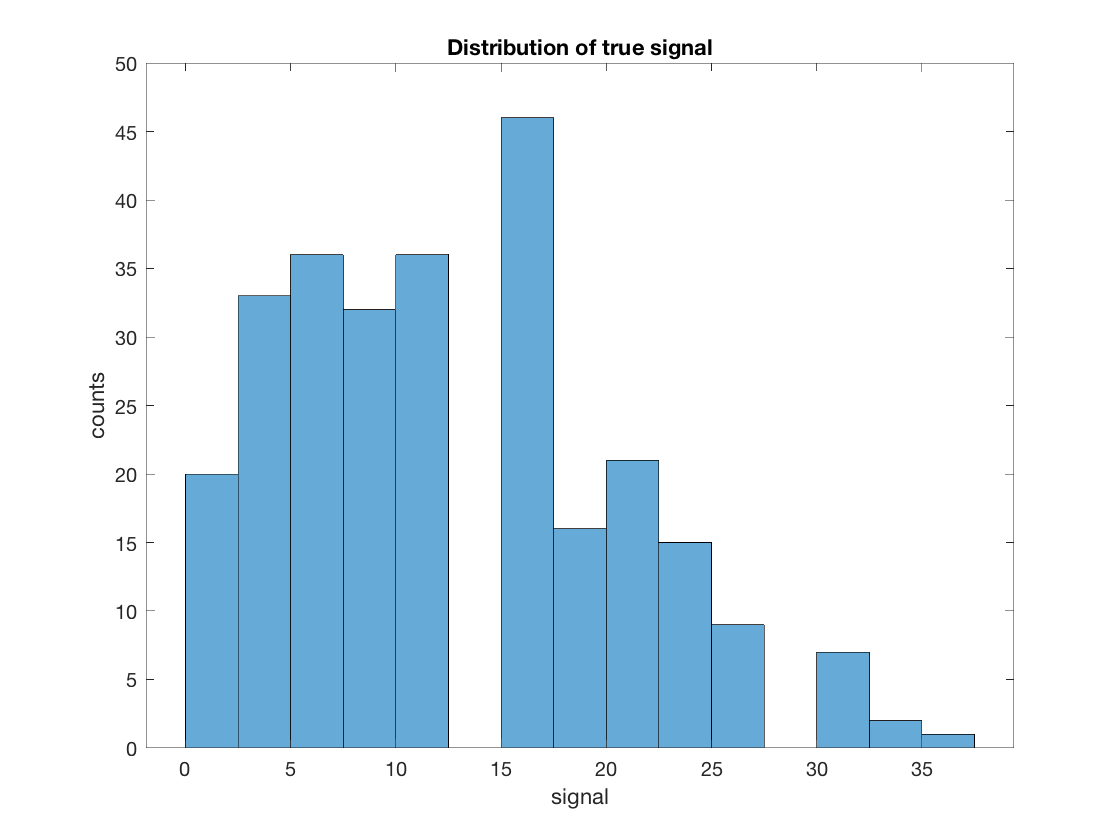


observation = 110;
injected = signal(abs(obssignal-observation)<0.05);
histogram(injected,15)
title('Distribution of true signal')
xlabel('signal')
ylabel('counts')

As the histogram shows, the distribution of the true signal extends to zero, it means that if we observe a signal that has the strength of 110, it is possible that we actually did not observe any true signal at all. 

In the second part of this section, I am going to establish the 95% confidence upper bound. As we are doing that, we are basically asking a statistical question: If I observe a candidate signal X, the probability of the true signal being smaller than X is 95%. What is the signal X?

To find X, I will pick a rang of candidate signal X and find the distribution of the true signal is the observed signal is X. Then I will integrate the pdf of true signal distribution and find the probability of the true signal being smaller than or equal to X. If the probability is equal to 95%, then X is our 95% confidence upper bound.

The code below will find X

observation = linspace(80,300,1000);
for i = 1:length(observation)
    threshold = 2*0.05;
    if threshold<=0.05
        break
    else
        injected = signal(abs(obssignal-observation(i))<0.05);
        pd = fitdist(injected,'Poisson');
        P = cdf(pd,observation(i));
        threshold = abs(P-0.95);
        X = observation(i);
    end
    
end

Becuase the background is very strong (has a mean of 100), the probability of the true signal being smaller than 80 (observed signal) is almost 1. It is almost impossible to find the distribution of the true signal if the observed signal is smaller 80 due to the high value of the background. Therefore, I am going to claim that the 95% confidence upper bound is 80. 